## **Question 1**

- Consider the the Lorenz-96 model (4) with the setting used in Project 1. The data assimilation problem is posed over the interval [0, T], starting with initial background states from N (x b 0 , B0). Observations are available at times ti = i ∆t, i = 0, . . . , N, tN = T. Use your synthetic observations, observation error covariance, and observation operator from Project 1.

**The code below is taken from my Project 1 implementation.**

**1.1)**

- Implement the Lorenz-96 model (1) and solve it using a Matlab ode solver (ode45 or one integrator selected from MATLODE).

- Start with an initial condition where the states are drawn from a random distribution (e.g., x0 ∼N (0, 16)), then integrate for 5 time units. Save the result. This is our x[-1]true.

- Propagate for ∆t time units, and save. This is our reference state x[0]true.

- (You can use ∆t = 0.1.)

clear;
close all;
clc;

% Setting seed for reproducibility
rng(381996)

% Importing Lorenz96 model
m = otp.lorenz63.presets.Canonical;

% Model configurations
n_states = 3;
n_obs = 5 % Number of observations

n_obs = 5

n_obs_states = 2;
x0 = normrnd(0,sqrt(16),[n_states,1]); % Inital condition of y0 drawn from N(0,16)
dt = 0.05; % time step unit

% Solving for for 5 time units (0.5) using inital conditions above
[~, x] = ode45(m.RHS.F, [0 dt*5], x0); % This is x[-1]true/reference state.
x_true_n1 = x(end,:).'; % Extracting states at final timestep

% Propogating for dt
[~, x] = ode45(m.RHS.F, [dt*5, dt*6], x_true_n1); % This is x[-1]true/reference state
x_true = x(end,:).'; % Extracting states at final timestep

**1.2)**

- Compute Nens normal random perturbations εbi ∼ N (0, σ2 INstate ) with σ = 0.2.

- Add to x[-1]true, and integrate the system starting from the perturbed initial conditions for ∆t time units.

- Save the resulting Nens states x. The members of this ensemble represent our set of background states Xb[0] .

n_ens = 1000;
sigma = 0.2;

% create ensemble members from perturbations of x_true
eps = normrnd(0,sigma,[n_states,n_ens]); % Perturbations (note normrnd(mu,sigma))
x_perturbed_n1 = x_true_n1 + eps;  % Adding to x_true[-1]

% init storage for ensemble (background state)
X_b_ens = zeros(n_states, n_ens);

% intergate system for one time unit for each ensemble member, store result
for i = 1:n_ens
    [~, x_ens] = ode45(m.RHS.F, [dt*5, dt*6], x_perturbed_n1(:, i));
    X_b_ens(:, i) = x_ens(end, :);
end

**1.3)**

- Using a large number of ensemble members compute the ensemble covariance Pb0.

- Check its condition number. If it is large build a modified background covariance that leads to a reasonably small condition number of the resulting covariance.

- This is our B0.

% A problem is called well-conditioned, if its condition number is small,
% i.e., in the order of 10, 100 or 1000
% and ill-conditioned if it is large: in the order of 10^6 - 10^10, and larger.
% https://cms.uni-konstanz.de/fileadmin/archive/informatik-saupe/fileadmin/informatik/ag-saupe/Webpages/lehre/na_08/Lab1/5_CondStab/html/CondStab.html

% Inbuilt covariance method
B0 = cov(X_b_ens.');
% Manual covariance check
X_ens_mean = mean(X_b_ens, 2);
X_delta = X_b_ens - X_ens_mean;
B0_manual = (1/(n_ens-1)).*(X_delta*X_delta.');

cond(B0), cond(B0_manual)

ans = 11.3549

ans = 11.3549

% Not needed as condition number is small
alpha = 0.001;
B0_downscale = (1-alpha)*B0 + alpha*eye(n_states);
cond(B0_downscale)

ans = 9.9081

% No need as already well conditioned
%B0 = B0_downscale

**1.4) **

- Obtain x0b by selecting one state with the smallest deviation from xtrue

[M,I] = min(sum(abs(X_b_ens - x_true(end,:).')));
x0b = X_b_ens(:, I)

x0b =   -19.9165
  -15.3658
   47.0913



% Hack work around as x0b was very far from the truth and all analysis
% probabilties were zero.
x_true

x_true =   -20.0487
  -16.0464
   47.1722


**1.5)**

- Run the reference trajectory starting from x_true[0] over the interval [0, T].

- Save the solution every ∆t time units.

- At each ti = i ∆t generate N_ens synthetic observations by adding to the reference solution H*xi normal random noise drawn from N (0, R), R = r^2 I N_obs, with r = 0.025.

T = 50;
time_steps = 0:dt:T;
x_start = x_true; % Storing inital x_true[0]

X_ref = zeros(n_states, length(time_steps));
X_ref(:, 1) = x_start;

% Run forward model and save results at each timestep
for t_id = 1:(length(time_steps)-1)
    [~, x] = ode45(m.RHS.F, [time_steps(t_id) time_steps(t_id)+dt], x_start);
    X_ref(:, t_id+1) = x(end,:);
    x_start = x(end,:).'; % For next iterations, use starting conditions based on prior state

end


% Apply observation operator and add random noise to reference trajectory

% Generating observation operator (observing every odd state)
A = eye(n_obs);
M = 1;
k = 1;
N = size(A);
H = reshape([reshape(A,M,[]);zeros(k,N(1)/M*N(2))],[],N(2)).';

% Redone such to only observe the first two states (For L63)
H = [1, 0, 0; 0, 1, 0]

H =      1     0     0
     0     1     0



% Applying observation vector to reference trajectory
% H * Reference -> Observations, Clone Observatations + noise -> ensemble 
X_obvs = H * X_ref;
X_obvs_ens = repmat(X_obvs, 1,1, n_obs);

% Generating and applying observation noise (for each ensemble member)
obvs_sigma = 0.025;
R = obvs_sigma.^2 * eye(n_obs_states);
obvs_noise = normrnd(0,obvs_sigma,size(X_obvs_ens));  % (note normrnd(mu,sigma))
X_obvs_ens = X_obvs_ens + obvs_noise;

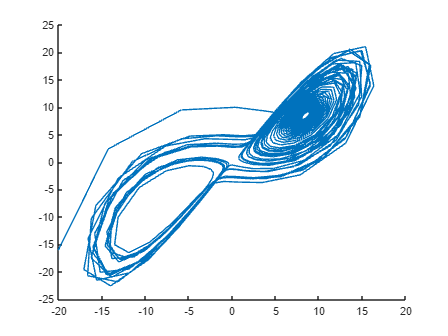

% Plotting sample reference and perturbed states (for 2 random ensemble members)
clf
hold on
plot3(X_ref(1, :), X_ref(2, :), X_ref(3, :));
%plot(X_obvs_ens(1, :, 1), X_obvs_ens(2, :, 1));
%plot(X_obvs_ens(1, :, 2), X_obvs_ens(2, :, 2));
hold off

## **Question 2**

**2.1)**

- Consider the data assimilation problem posed over the interval [0, T], starting with initial background states from N (xb[0] , B0).

- Observations are available at times ti = i ∆t, i = 0, . . . , N, tN = T. Use your synthetic observations, observation error covariance, and observation operator from above.

% Unclear if these need to be resampled from this distribution or use the previously generated ensemble
n_particles = 1000

n_particles = 1000

X_ens_b = mvnrnd(x0b, B0, n_particles).'; 

**2.2)**

- Solve the data assimilation problem using the standard sequential importance with resampling (SIR) particle filter. 

- Resample when the effective number of particles decreases below a fraction of the total number, Neff ens ≤ α Nens, with 0 < α < 1 a tuning parameter under your control.

w = 1.0e-03 *

    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


X_prediction =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


n_eff = 1.0000

Reampling!


n_eff = 995.9199

n_eff = 989.7194

n_eff = 985.4033

n_eff = 965.6521

n_eff = 965.0205

n_eff = 965.0071

n_eff = 954.9177

n_eff = 937.7732

n_eff = 842.7592

n_eff = 814.8389

n_eff = 729.9153

n_eff = 733.2059

n_eff = 728.9050

n_eff = 694.3039

n_eff = 657.8571

n_eff = 651.1494

n_eff = 469.4585

n_eff = 489.5394

n_eff = 395.6443

n_eff = 311.1745

n_eff = 216.1317

n_eff = 165.5267

n_eff = 112.3721

n_eff = 114.4255

n_eff = 114.0403

n_eff = 101.5985

n_eff = 46.4448

Reampling!


n_eff = 988.5743

n_eff = 988.4459

n_eff = 969.9082

n_eff = 979.6043

n_eff = 939.8065

n_eff = 824.3439

n_eff = 781.4041

n_eff = 745.4690

n_eff = 736.1672

n_eff = 655.3913

n_eff = 670.5820

n_eff = 553.9879

n_eff = 389.2138

n_eff = 286.1133

n_eff = 221.4058

n_eff = 192.6820

n_eff = 146.5902

n_eff = 144.5651

n_eff = 73.0383

Reampling!


n_eff = 962.6523

n_eff = 956.3206

n_eff = 912.8300

n_eff = 660.9754

n_eff = 605.0572

n_eff = 521.1317

n_eff = 297.4732

n_eff = 292.7205

n_eff = 288.4549

n_eff = 295.7869

n_eff = 239.7567

n_eff = 230.8605

n_eff = 131.5052

n_eff = 129.9355

n_eff = 143.7784

n_eff = 158.3866

n_eff = 86.9829

Reampling!


n_eff = 824.1516

n_eff = 859.0422

n_eff = 464.2298

n_eff = 565.9179

n_eff = 560.4546

n_eff = 548.8336

n_eff = 567.3709

n_eff = 447.2427

n_eff = 402.7911

n_eff = 455.4166

n_eff = 394.9176

n_eff = 339.1455

n_eff = 333.6701

n_eff = 190.5195

n_eff = 129.7205

n_eff = 120.9910

n_eff = 121.0914

n_eff = 119.9966

n_eff = 122.2936

n_eff = 97.5304

Reampling!


n_eff = 989.7552

n_eff = 930.4546

n_eff = 912.0619

n_eff = 737.1913

n_eff = 583.2056

n_eff = 545.3134

n_eff = 528.5120

n_eff = 528.2519

n_eff = 534.7110

n_eff = 605.7227

n_eff = 685.2708

n_eff = 700.8832

n_eff = 694.5069

n_eff = 526.6201

n_eff = 492.0060

n_eff = 452.4787

n_eff = 431.9107

n_eff = 430.3123

n_eff = 488.3936

n_eff = 544.5709

n_eff = 522.0896

n_eff = 492.1915

n_eff = 479.4981

n_eff = 402.8918

n_eff = 334.1912

n_eff = 324.2760

n_eff = 303.4218

n_eff = 291.5237

n_eff = 359.4757

n_eff = 296.0237

n_eff = 297.6922

n_eff = 305.8073

n_eff = 220.4441

n_eff = 192.7986

n_eff = 194.7517

n_eff = 174.2830

n_eff = 165.2412

n_eff = 153.9056

n_eff = 173.4771

n_eff = 170.5800

n_eff = 149.2454

n_eff = 148.6995

n_eff = 168.3646

n_eff = 165.9430

n_eff = 156.0434

n_eff = 156.9174

n_eff = 154.4790

n_eff = 163.2912

n_eff = 161.6246

n_eff = 171.8997

n_eff = 169.0600

n_eff = 167.6270

n_eff = 165.7472

n_eff = 156.8431

n_eff = 159.0568

n_eff = 141.1097

n_eff = 158.6849

n_eff = 132.1019

n_eff = 115.1589

n_eff = 117.9595

n_eff = 105.3169

n_eff = 94.9332

Reampling!


n_eff = 985.5162

n_eff = 956.0402

n_eff = 922.9581

n_eff = 899.7676

n_eff = 871.1135

n_eff = 859.6313

n_eff = 846.1566

n_eff = 839.7462

n_eff = 802.4384

n_eff = 801.4513

n_eff = 796.0275

n_eff = 749.9897

n_eff = 797.3114

n_eff = 751.6149

n_eff = 601.1134

n_eff = 601.4673

n_eff = 611.9971

n_eff = 599.5396

n_eff = 582.8194

n_eff = 499.1420

n_eff = 396.6264

n_eff = 437.5303

n_eff = 486.2296

n_eff = 504.7461

n_eff = 507.9601

n_eff = 497.2053

n_eff = 508.6738

n_eff = 531.2632

n_eff = 519.3679

n_eff = 468.2775

n_eff = 450.1059

n_eff = 341.7239

n_eff = 338.5611

n_eff = 332.1466

n_eff = 289.6371

n_eff = 266.5287

n_eff = 215.8866

n_eff = 209.6384

n_eff = 224.5664

n_eff = 200.1297

n_eff = 200.6243

n_eff = 185.1735

n_eff = 104.2205

n_eff = 93.1461

Reampling!


n_eff = 998.3856

n_eff = 816.9326

n_eff = 913.4256

n_eff = 898.3262

n_eff = 552.4822

n_eff = 546.8660

n_eff = 521.9269

n_eff = 348.6149

n_eff = 573.1374

n_eff = 544.0415

n_eff = 414.4882

n_eff = 328.0208

n_eff = 411.2728

n_eff = 262.9786

n_eff = 249.1122

n_eff = 250.0596

n_eff = 232.1344

n_eff = 193.5564

n_eff = 200.2376

n_eff = 195.4583

n_eff = 163.7310

n_eff = 130.9217

n_eff = 101.9224

n_eff = 105.8838

n_eff = 99.4675

Reampling!


n_eff = 874.6719

n_eff = 870.0058

n_eff = 768.1207

n_eff = 589.0872

n_eff = 474.8022

n_eff = 379.8166

n_eff = 346.4666

n_eff = 312.5425

n_eff = 438.6991

n_eff = 402.5701

n_eff = 319.8833

n_eff = 272.5964

n_eff = 270.1971

n_eff = 264.8945

n_eff = 235.0909

n_eff = 229.2860

n_eff = 195.4022

n_eff = 148.7694

n_eff = 173.7883

n_eff = 156.8585

n_eff = 141.7411

n_eff = 162.3820

n_eff = 123.6063

n_eff = 146.9366

n_eff = 144.8898

n_eff = 126.1209

n_eff = 149.7221

n_eff = 144.5063

n_eff = 113.8329

n_eff = 127.2793

n_eff = 123.6478

n_eff = 124.7420

n_eff = 100.7028

n_eff = 81.7644

Reampling!


n_eff = 990.0810

n_eff = 935.2748

n_eff = 930.3261

n_eff = 879.2785

n_eff = 854.1396

n_eff = 674.8886

n_eff = 708.2742

n_eff = 677.9658

n_eff = 846.7460

n_eff = 848.0109

n_eff = 842.7158

n_eff = 631.4796

n_eff = 734.2121

n_eff = 688.5598

n_eff = 688.5578

n_eff = 660.4930

n_eff = 654.6673

n_eff = 517.4453

n_eff = 508.9372

n_eff = 607.7630

n_eff = 632.8875

n_eff = 600.1782

n_eff = 449.3275

n_eff = 408.6899

n_eff = 422.9253

n_eff = 445.3361

n_eff = 427.5169

n_eff = 472.3006

n_eff = 313.1077

n_eff = 294.3718

n_eff = 268.3720

n_eff = 253.3530

n_eff = 248.7236

n_eff = 215.6619

n_eff = 199.7461

n_eff = 155.4736

n_eff = 138.2544

n_eff = 134.9031

n_eff = 128.8012

n_eff = 130.5028

n_eff = 156.8019

n_eff = 187.1995

n_eff = 199.3008

n_eff = 195.5947

n_eff = 178.7771

n_eff = 184.7180

n_eff = 171.0746

n_eff = 170.7306

n_eff = 169.1535

n_eff = 164.6019

n_eff = 148.7949

n_eff = 146.1360

n_eff = 129.6532

n_eff = 119.3795

n_eff = 116.5261

n_eff = 102.2282

n_eff = 82.6340

Reampling!


n_eff = 952.5873

n_eff = 625.9116

n_eff = 571.9673

n_eff = 570.2501

n_eff = 568.8998

n_eff = 551.5476

n_eff = 389.1117

n_eff = 380.4899

n_eff = 366.2368

n_eff = 361.9699

n_eff = 370.1463

n_eff = 354.3360

n_eff = 336.7559

n_eff = 269.9007

n_eff = 270.7680

n_eff = 204.9007

n_eff = 205.7931

n_eff = 241.1678

n_eff = 261.8339

n_eff = 280.2217

n_eff = 258.0955

n_eff = 279.6690

n_eff = 274.7768

n_eff = 268.3062

n_eff = 248.8908

n_eff = 231.4944

n_eff = 249.8312

n_eff = 218.9560

n_eff = 230.5905

n_eff = 227.5812

n_eff = 224.4882

n_eff = 193.0599

n_eff = 184.2587

n_eff = 190.1548

n_eff = 133.2825

n_eff = 135.8784

n_eff = 136.1395

n_eff = 119.5273

n_eff = 111.7594

n_eff = 101.7061

n_eff = 92.9081

Reampling!


n_eff = 966.2256

n_eff = 941.7432

n_eff = 941.5204

n_eff = 948.0609

n_eff = 945.5039

n_eff = 934.4253

n_eff = 924.6782

n_eff = 908.3372

n_eff = 707.4986

n_eff = 672.6574

n_eff = 641.1739

n_eff = 528.4523

n_eff = 532.5528

n_eff = 475.9570

n_eff = 553.5325

n_eff = 510.7298

n_eff = 508.3072

n_eff = 489.0491

n_eff = 550.8652

n_eff = 413.3478

n_eff = 415.5177

n_eff = 538.6190

n_eff = 545.2032

n_eff = 546.5210

n_eff = 518.2587

n_eff = 509.5014

n_eff = 483.9382

n_eff = 479.0737

n_eff = 475.2864

n_eff = 456.9556

n_eff = 460.6516

n_eff = 440.0877

n_eff = 433.0200

n_eff = 420.7406

n_eff = 354.7281

n_eff = 312.8449

n_eff = 263.2477

n_eff = 258.0377

n_eff = 246.7839

n_eff = 233.4069

n_eff = 237.0011

n_eff = 268.3699

n_eff = 264.6360

n_eff = 260.5211

n_eff = 236.4910

n_eff = 223.7810

n_eff = 222.6640

n_eff = 215.5451

n_eff = 210.0521

n_eff = 205.2584

n_eff = 175.6419

n_eff = 176.1399

n_eff = 121.7832

n_eff = 121.0721

n_eff = 139.0425

n_eff = 139.3377

n_eff = 131.3926

n_eff = 126.9259

n_eff = 121.8052

n_eff = 107.9599

n_eff = 93.0905

Reampling!


n_eff = 985.5172

n_eff = 964.2531

n_eff = 944.8370

n_eff = 920.1404

n_eff = 408.2200

n_eff = 245.1205

n_eff = 281.0357

n_eff = 161.2302

n_eff = 105.8793

n_eff = 117.9873

n_eff = 150.7703

n_eff = 143.9763

n_eff = 146.8835

n_eff = 214.6802

n_eff = 229.0571

n_eff = 235.3932

n_eff = 223.8182

n_eff = 182.7387

n_eff = 164.5035

n_eff = 157.8452

n_eff = 187.0088

n_eff = 188.5403

n_eff = 190.9795

n_eff = 190.3144

n_eff = 181.3377

n_eff = 150.4424

n_eff = 91.0912

Reampling!


n_eff = 971.4793

n_eff = 988.0141

n_eff = 866.2794

n_eff = 865.2913

n_eff = 799.4848

n_eff = 708.7772

n_eff = 761.3572

n_eff = 776.9840

n_eff = 761.6073

n_eff = 805.3193

n_eff = 792.9910

n_eff = 634.1437

n_eff = 371.0174

n_eff = 254.8691

n_eff = 172.4356

n_eff = 157.0493

n_eff = 228.1172

n_eff = 209.7420

n_eff = 220.0926

n_eff = 224.8165

n_eff = 228.4992

n_eff = 214.9007

n_eff = 219.4358

n_eff = 219.6568

n_eff = 214.5266

n_eff = 197.6948

n_eff = 193.9745

n_eff = 183.4666

n_eff = 123.5381

n_eff = 119.9191

n_eff = 118.7572

n_eff = 98.3002

Reampling!


n_eff = 841.1488

n_eff = 817.9022

n_eff = 801.6704

n_eff = 829.3871

n_eff = 823.6242

n_eff = 748.7175

n_eff = 802.6533

n_eff = 697.7192

n_eff = 687.4215

n_eff = 224.7790

n_eff = 209.0412

n_eff = 261.5553

n_eff = 190.3845

n_eff = 122.6433

n_eff = 111.2511

n_eff = 91.1682

Reampling!


n_eff = 996.7783

n_eff = 842.8777

n_eff = 615.9718

n_eff = 555.2517

n_eff = 510.7554

n_eff = 504.4033

n_eff = 483.3267

n_eff = 484.2219

n_eff = 429.0034

n_eff = 382.5209

n_eff = 393.5607

n_eff = 392.3396

n_eff = 387.7308

n_eff = 372.8310

n_eff = 203.3932

n_eff = 208.1688

n_eff = 202.3175

n_eff = 220.5963

n_eff = 250.3013

n_eff = 231.3266

n_eff = 195.5653

n_eff = 219.2057

n_eff = 198.2748

n_eff = 180.9993

n_eff = 131.3917

n_eff = 110.5186

n_eff = 93.3184

Reampling!


n_eff = 968.0953

n_eff = 893.6703

n_eff = 805.4173

n_eff = 650.9340

n_eff = 309.5102

n_eff = 269.2324

n_eff = 293.8249

n_eff = 299.0912

n_eff = 305.2510

n_eff = 303.2964

n_eff = 271.9884

n_eff = 273.0570

n_eff = 243.8182

n_eff = 220.3149

n_eff = 219.8146

n_eff = 217.4696

n_eff = 214.9224

n_eff = 206.6679

n_eff = 182.6980

n_eff = 185.5834

n_eff = 175.4098

n_eff = 177.7203

n_eff = 176.2056

n_eff = 172.4015

n_eff = 172.4713

n_eff = 150.6305

n_eff = 98.2588

Reampling!


n_eff = 935.7677

n_eff = 365.7612

n_eff = 137.8229

n_eff = 133.0230

n_eff = 106.9607

n_eff = 86.0907

Reampling!


n_eff = 858.5617

n_eff = 451.4120

n_eff = 630.9662

n_eff = 611.1401

n_eff = 591.7339

n_eff = 521.8341

n_eff = 417.7850

n_eff = 438.2585

n_eff = 406.8954

n_eff = 431.5192

n_eff = 474.9706

n_eff = 477.3665

n_eff = 472.1664

n_eff = 442.9229

n_eff = 438.2412

n_eff = 276.5412

n_eff = 242.5490

n_eff = 238.9238

n_eff = 248.1901

n_eff = 251.4404

n_eff = 241.5960

n_eff = 242.7089

n_eff = 185.9497

n_eff = 224.9286

n_eff = 203.5454

n_eff = 169.4270

n_eff = 147.0800

n_eff = 99.6065

Reampling!


n_eff = 801.1745

n_eff = 402.4428

n_eff = 352.4593

n_eff = 332.6577

n_eff = 276.8332

n_eff = 161.1657

n_eff = 151.5778

n_eff = 151.5495

n_eff = 152.1593

n_eff = 157.1217

n_eff = 149.9587

n_eff = 147.8280

n_eff = 171.0858

n_eff = 170.7813

n_eff = 166.5639

n_eff = 132.4464

n_eff = 150.7852

n_eff = 148.8318

n_eff = 130.1655

n_eff = 97.3935

Reampling!


n_eff = 992.6258

n_eff = 910.4198

n_eff = 859.1231

n_eff = 847.0794

n_eff = 852.1631

n_eff = 834.5048

n_eff = 770.3777

n_eff = 586.9065

n_eff = 495.9075

n_eff = 302.2874

n_eff = 322.1507

n_eff = 292.2063

n_eff = 281.3782

n_eff = 265.6033

n_eff = 215.4623

n_eff = 205.3982

n_eff = 192.8137

n_eff = 188.1595

n_eff = 185.3315

n_eff = 196.3722

n_eff = 190.3442

n_eff = 188.2650

n_eff = 131.9527

n_eff = 95.9463

Reampling!


n_eff = 709.9074

n_eff = 453.9335

n_eff = 99.1014

Reampling!


n_eff = 820.6029

n_eff = 737.8955

n_eff = 592.1469

n_eff = 401.4318

n_eff = 338.2613

n_eff = 251.6546

n_eff = 229.6643

n_eff = 245.3582

n_eff = 201.4527

n_eff = 196.1766

n_eff = 132.9819

n_eff = 168.4281

n_eff = 153.5700

n_eff = 58.0502

Reampling!


n_eff = 991.6358

n_eff = 817.1007

n_eff = 794.6319

n_eff = 802.5675

n_eff = 790.9642

n_eff = 798.1044

n_eff = 752.7512

n_eff = 750.2349

n_eff = 592.2489

n_eff = 633.7643

n_eff = 725.9437

n_eff = 716.8339

n_eff = 644.3910

n_eff = 620.9387

n_eff = 428.7411

n_eff = 231.5319

n_eff = 202.6329

n_eff = 151.1043

n_eff = 161.9059

n_eff = 155.4442

n_eff = 116.7352

n_eff = 117.5699

n_eff = 101.7650

n_eff = 101.7108

n_eff = 101.8643

n_eff = 85.9080

Reampling!


n_eff = 880.3410

n_eff = 916.1958

n_eff = 956.2708

n_eff = 857.9656

n_eff = 850.8238

n_eff = 853.1747

n_eff = 776.9561

n_eff = 693.9523

n_eff = 595.3437

n_eff = 549.6665

n_eff = 468.1272

n_eff = 354.5616

n_eff = 444.6748

n_eff = 383.8368

n_eff = 375.9922

n_eff = 448.3123

n_eff = 440.5068

n_eff = 368.6202

n_eff = 313.3696

n_eff = 217.1858

n_eff = 150.5251

n_eff = 97.8871

Reampling!


n_eff = 834.2457

n_eff = 737.2728

n_eff = 339.1515

n_eff = 313.4576

n_eff = 386.1173

n_eff = 374.4606

n_eff = 318.4283

n_eff = 274.5449

n_eff = 274.1296

n_eff = 276.2374

n_eff = 285.2247

n_eff = 265.2046

n_eff = 214.4177

n_eff = 198.1833

n_eff = 223.6157

n_eff = 194.7359

n_eff = 179.6604

n_eff = 156.7217

n_eff = 152.8548

n_eff = 153.6191

n_eff = 151.4460

n_eff = 141.2205

n_eff = 143.2069

n_eff = 131.4540

n_eff = 131.3364

n_eff = 120.9444

n_eff = 112.0291

n_eff = 109.6263

n_eff = 87.5913

Reampling!


n_eff = 904.5387

n_eff = 329.0814

n_eff = 330.8069

n_eff = 323.7579

n_eff = 365.1813

n_eff = 271.0908

n_eff = 258.6740

n_eff = 201.6282

n_eff = 194.3857

n_eff = 178.1808

n_eff = 175.0643

n_eff = 180.1911

n_eff = 209.6791

n_eff = 175.2567

n_eff = 191.3353

n_eff = 164.8050

n_eff = 115.1136

n_eff = 109.3984

n_eff = 115.7544

n_eff = 110.6294

n_eff = 101.0076

n_eff = 100.8006

n_eff = 95.5656

Reampling!


n_eff = 999.8190

n_eff = 997.1573

n_eff = 935.1014

n_eff = 717.4180

n_eff = 721.4278

n_eff = 406.1352

n_eff = 298.7369

n_eff = 376.4798

n_eff = 272.5709

n_eff = 242.8159

n_eff = 196.5457

n_eff = 91.8038

Reampling!


n_eff = 991.5239

n_eff = 989.2991

n_eff = 355.3961

n_eff = 470.2045

n_eff = 479.6948

n_eff = 489.3199

n_eff = 493.3601

n_eff = 459.7964

n_eff = 432.4131

n_eff = 456.6723

n_eff = 436.5206

n_eff = 393.0543

n_eff = 379.2870

n_eff = 347.7332

n_eff = 351.5943

n_eff = 346.5857

n_eff = 344.0742

n_eff = 363.0571

n_eff = 329.3164

n_eff = 292.5318

n_eff = 268.9815

n_eff = 261.9519

n_eff = 278.4059

n_eff = 292.2411

n_eff = 251.8840

n_eff = 248.5336

n_eff = 226.0883

n_eff = 212.8226

n_eff = 214.7416

n_eff = 194.9443

n_eff = 170.6627

n_eff = 167.2004

n_eff = 161.1521

n_eff = 160.5722

n_eff = 150.5671

n_eff = 142.1153

n_eff = 148.0471

n_eff = 136.7315

n_eff = 68.7657

Reampling!


n_eff = 974.5484

n_eff = 916.4779

n_eff = 802.7262

n_eff = 728.3240

n_eff = 652.3428

n_eff = 574.8481

n_eff = 359.5289

n_eff = 286.7419

n_eff = 282.7291

n_eff = 280.9359

n_eff = 274.5532

n_eff = 271.1867

n_eff = 255.2233

n_eff = 254.8470

n_eff = 247.0526

n_eff = 246.5133

n_eff = 138.4025

n_eff = 147.1175

n_eff = 126.2480

n_eff = 68.7019

Reampling!


n_eff = 970.8628

n_eff = 965.3739

n_eff = 837.5956

n_eff = 597.5650

n_eff = 597.5883

n_eff = 612.3765

n_eff = 603.6537

n_eff = 519.6592

n_eff = 504.0968

n_eff = 506.2313

n_eff = 534.5643

n_eff = 432.1036

n_eff = 490.9176

n_eff = 400.2864

n_eff = 405.2642

n_eff = 398.6752

n_eff = 304.4938

n_eff = 361.8762

n_eff = 331.5903

n_eff = 317.7754

n_eff = 272.6958

n_eff = 253.2840

n_eff = 139.5015

n_eff = 143.3804

n_eff = 121.6035

n_eff = 176.5335

n_eff = 195.9332

n_eff = 163.7937

n_eff = 121.2108

n_eff = 86.9269

Reampling!


n_eff = 862.6867

n_eff = 565.0537

n_eff = 534.7670

n_eff = 514.7825

n_eff = 305.6181

n_eff = 263.8495

n_eff = 261.4839

n_eff = 266.4293

n_eff = 263.1333

n_eff = 265.0263

n_eff = 264.6261

n_eff = 257.9970

n_eff = 259.8955

n_eff = 256.3462

n_eff = 244.9406

n_eff = 173.3879

n_eff = 192.3510

n_eff = 145.6918

n_eff = 155.2847

n_eff = 139.0292

n_eff = 120.0425

n_eff = 130.7474

n_eff = 132.5865

n_eff = 133.8287

n_eff = 133.5050

n_eff = 133.1783

n_eff = 113.8498

n_eff = 109.9287

n_eff = 100.6811

n_eff = 78.9945

Reampling!


n_eff = 945.5553

n_eff = 784.2234

n_eff = 667.3378

n_eff = 589.0619

n_eff = 525.8677

n_eff = 512.6726

n_eff = 530.2600

n_eff = 532.7895

n_eff = 529.7183

n_eff = 490.9646

n_eff = 429.8336

n_eff = 407.9862

n_eff = 375.0213

n_eff = 320.7400

n_eff = 226.1708

n_eff = 167.9455

n_eff = 143.5985

n_eff = 96.3692

Reampling!


n_eff = 658.1541

n_eff = 476.0581

n_eff = 484.9602

n_eff = 277.5260

n_eff = 228.3860

n_eff = 213.2473

n_eff = 209.1152

n_eff = 208.0854

n_eff = 208.8489

n_eff = 205.8696

n_eff = 200.1101

n_eff = 197.2669

n_eff = 196.3671

n_eff = 192.8864

n_eff = 186.4661

n_eff = 187.1696

n_eff = 148.9725

n_eff = 101.2943

n_eff = 100.3062

n_eff = 106.2962

n_eff = 107.2051

n_eff = 97.6762

Reampling!


n_eff = 759.3813

n_eff = 713.7158

n_eff = 509.1433

n_eff = 480.8300

n_eff = 404.6279

n_eff = 257.1341

n_eff = 269.9988

n_eff = 289.7944

n_eff = 128.4677

n_eff = 171.1556

n_eff = 150.6515

n_eff = 180.3674

n_eff = 129.4947

n_eff = 105.4586

n_eff = 114.2687

n_eff = 140.7871

n_eff = 145.6321

n_eff = 203.5785

n_eff = 190.7839

n_eff = 165.6993

n_eff = 164.0756

n_eff = 166.7503

n_eff = 109.6217

n_eff = 95.3177

Reampling!


n_eff = 994.0697

n_eff = 986.5320

n_eff = 958.0746

n_eff = 951.1690

n_eff = 970.7913

n_eff = 945.2603

n_eff = 666.5086

n_eff = 712.4657

n_eff = 397.7615

n_eff = 367.9977

n_eff = 325.1315

n_eff = 328.0192

n_eff = 249.0479

n_eff = 224.7695

n_eff = 183.1822

n_eff = 171.3416

n_eff = 156.4544

n_eff = 156.7947

n_eff = 155.0662

n_eff = 98.0828

Reampling!


n_eff = 974.5812

n_eff = 922.6084

n_eff = 912.9847

n_eff = 459.5517

n_eff = 477.7076

n_eff = 364.0459

n_eff = 212.2586

n_eff = 151.9074

n_eff = 115.8050

n_eff = 62.5627

Reampling!


n_eff = 834.1325

n_eff = 773.0651

n_eff = 584.6592

n_eff = 569.2618

n_eff = 566.6437

n_eff = 551.2289

n_eff = 549.5076

n_eff = 533.5755

n_eff = 537.9832

n_eff = 540.5858

n_eff = 527.1623

n_eff = 524.8218

n_eff = 501.5578

n_eff = 514.2682

n_eff = 501.7624

n_eff = 474.0851

n_eff = 460.7693

n_eff = 428.0156

n_eff = 426.9125

n_eff = 416.6144

n_eff = 449.8754

n_eff = 438.0093

n_eff = 438.0272

n_eff = 416.9176

n_eff = 371.9389

n_eff = 325.7094

n_eff = 314.7644

n_eff = 312.8314

n_eff = 299.4879

n_eff = 293.6252

n_eff = 280.5537

n_eff = 259.7432

n_eff = 257.1057

n_eff = 247.8069

n_eff = 240.9200

n_eff = 252.3029

n_eff = 247.6669

n_eff = 228.3167

n_eff = 192.9345

n_eff = 160.1283

n_eff = 131.0232

n_eff = 122.7551

n_eff = 144.5033

n_eff = 104.1906

EnKF run complete


rmse_particle =     0.4057    0.0297    0.0219    0.0175    0.0163    0.0158    0.0149    0.0134    0.0122    0.0125    0.0139    0.0151    0.0148    0.0135    0.0125    0.0128    0.0141    0.0151    0.0146    0.0135    0.0120    0.0117    0.0128    0.0140    0.0142    0.0131    0.0119    0.0117    0.0121    0.0130    0.0133    0.0124    0.0112    0.0104    0.0109    0.0122    0.0129    0.0123    0.0111    0.0105    0.0108    0.0115    0.0117    0.0111    0.0099    0.0091    0.0095    0.0100    0.0106    0.0104


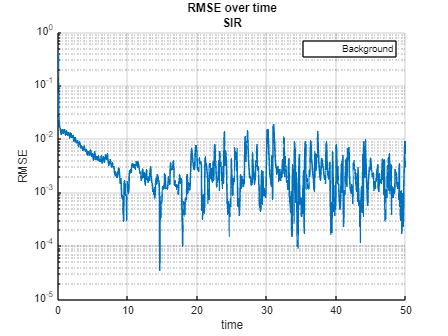

prediction = donald_SIR_63b(m, X_ens_b, X_obvs_ens, X_ref, H, time_steps, n_states, n_particles, 1);

**2.3)**

- Solve the data assimilation problem using a square root filter (EnSRF), e.g., ETKF.

- You will need to implement the filter, run it, and assess the quality of the results.

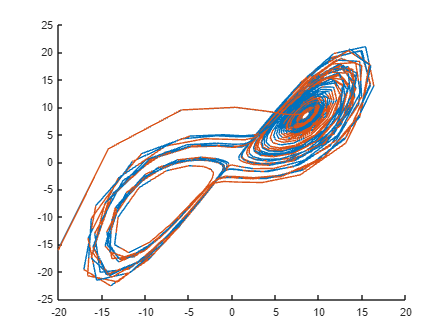

clf
hold on
plot3(prediction(1, :), prediction(2, :), prediction(3, :));
plot3(X_ref(1, :), X_ref(2, :), X_ref(3, :));

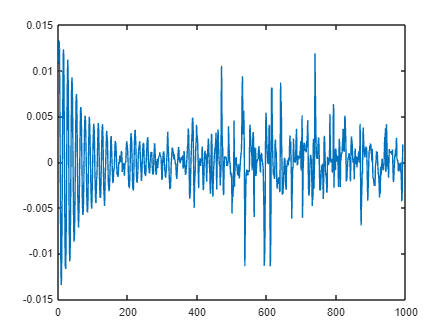


clf
plot(prediction(1, 10:end)-X_ref(1, 10:end))

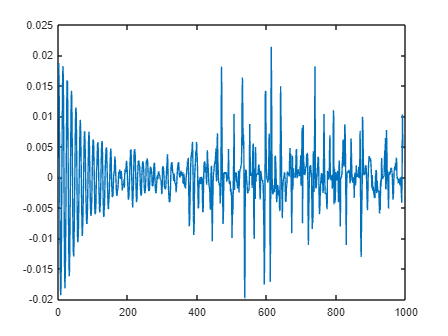

plot(prediction(2, 10:end)-X_ref(2, 10:end))

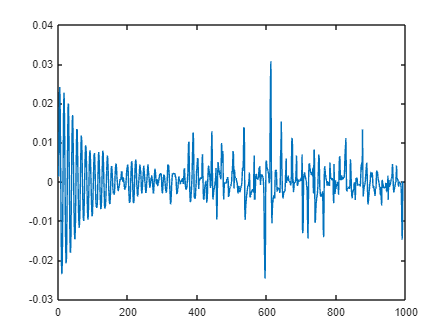

plot(prediction(3, 10:end)-X_ref(3, 10:end))

**2.4)**

For each case plot: 

- The time evolution of the error in the analysis ensemble mean, compared to the reference trajectory.

- The rank histogram for one of the observations.

% Done above

**2.5)**

- Apply covariance localization. Use a Gaspari-Cohn function with a decorrelation parameter L = 5.

- Repeat the EnKF and ETKF numerical experiments and compare the results against the analysis obtained without localization.

% Updated filter configurations (covar localization)
covar_localization = 1; % True
covar_inflation = 0; % False

[X_ens_array] = donald_EnKF(m, X_ens_b, X_obvs_ens,X_ref, H, time_steps, R, n_states, n_ens, covar_localization, covar_inflation, L, alpha, plot);
[X_ens_array] = donald_LETKF(m, X_ens_b,X_obvs, X_obvs_ens, X_ref, H, time_steps, n_states, n_ens, covar_inflation, L, alpha, plot);

**2.6)**

- In addition to localization, apply multiplicative covariance inflation with a parameter α = 1.02.

-  Again, repeat the EnKF and ETKF numerical experiments, and compare the results against the analysis obtained before. 

% Filter configurations (localization and covar inflation)
covar_localization = 1; % True
covar_inflation = 1; % False


[X_ens_array] = donald_EnKF(m, X_ens_b, X_obvs_ens,X_ref, H, time_steps, R, n_states, n_ens, covar_localization, covar_inflation, L, alpha, plot);
covar_localization = 0; % Should be True - but localization for ETKF not implemented yet!

[X_ens_array] = donald_LETKF(m, X_ens_b, X_obvs, X_obvs_ens, X_ref, H, time_steps, n_states, n_ens, covar_inflation, L, alpha, plot);